# Train Generative Adversarial Network (GAN)[1]

敵対的生成ネットワーク(GAN)を文字画像を用いて学習してみましょう。

GANは二つのネットワークで構成されています。

- Generator — 生成ネットワーク。ノイズが与えられたとき、学習した画像の分布に合うような画像を生成する。

- Discriminator — 識別ネットワーク。学習画像とGeneratorから生成された画像をそれぞれ"本物"と"偽物"に分類する。

下の図はGANの学習方法を示しています。

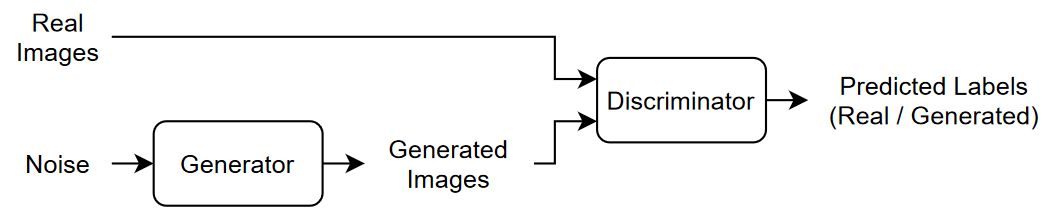

生成ネットワークと識別ネットワークはそれぞれ次のように学習します。

- 生成ネットワークは識別ネットワークを騙すように(本物だと間違えるように)学習します。

- 識別ネットワークは本物の画像と生成ネットワークから生成された画像を見分けるように学習します。

GANはこの二つのモデルを互いに学習することで互いに関係を持ち、学習を促すことにより高度な生成モデルになります。

今回はデジタル数字データセットであるMNISTを用いてGANを学習させます。

## 学習データの読み込み

**ここは変更しないでください。**

[MNISTデータセット](https://paperswithcode.com/dataset/mnist)は一万枚のデジタル数字データセットです。0から9の番号があり通常は識別で使用されますが、今回は生成する画像として学習します。

1万枚のデータを使うと学習に時間がかかるため今回は5000枚の0から4の画像を用いて学習を行います。

[MNISTデータセット](https://paperswithcode.com/dataset/mnist)をダウンロードします。

clear;clc;close all force
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', 'nndatasets','DigitDataset');

データストアに画像を保存します。

imds = imageDatastore(digitDatasetPath,IncludeSubfolders=true);
imds = partition(imds,2,1);

MNISTの画像サイズは28×28ピクセルですが、学習をしやすくするため32×32ピクセルに変更します。

augimds = augmentedImageDatastore([32 32],imds);

## GANモデルの定義

**ここは変更しないでください。**

GeneratorとDiscriminatorを定義します。

### Generatorの定義

今回のGeneratorは Noise_dim 次元のノイズベクトルから全結合層を用いてノイズマップに変換しています。

Noise_map_sizeは H×W×dim になっておりdimを変更することで精度が変化します。HとWは4に固定してください。

Noise mapに変換した後は3つのdeconvolution層によって32×32×1になります。

変更していい箇所は以下の部分です。

- 途中のConvolution層、活性化関数、バッチノーマライゼーション、などの追加、削除

- Convolution層のフィルタサイズや次元数の設定

モデルを変更する際の注意点は次のようになります。

- 出力サイズは32×32×1になるように調整すること

- 出力の最後の活性化関数はtanhであること

scale = 0.2;
filterSize = 5;
numFilters = 64;
Noise_dim = 512;

Noise_map_size = [4 4 512];

layersGenerator = [
    featureInputLayer(Noise_dim)
    projectAndReshapeLayer(Noise_map_size)
    transposedConv2dLayer(filterSize,256)
    batchNormalizationLayer
    leakyReluLayer(scale)
    transposedConv2dLayer(filterSize,128,Stride=2,Cropping="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    transposedConv2dLayer(filterSize,1,Stride=2,Cropping="same")
    tanhLayer];

netG = dlnetwork(layersGenerator);

### Discriminatorの定義

**ここは変更しないでください。**

Discriminatorは本物の画像と生成された画像を識別するネットワークです。今回は32×32×1の数字画像を本物か偽物か識別するように学習します。

活性化関数は一般的にLeakyReluがいいとされていますが、データセットによって他の活性化関数がいい場合があります。

変更指定医箇所は以下の部分です。

- 各種パラメータ

- 途中のConvolution層、活性化関数、バッチノーマライゼーション、などの追加、削除

- Convolution層のフィルタサイズや次元数の設定

モデルを変更する際の注意点は次のようになります。

- 入力サイズは32×32×1なため、特徴マップの圧縮は最大で5回まで

- 出力の最後の次元数は1にし、活性化関数sigmoid関数を用いること

scale = 0.2;
dropoutProb = 0.10;
inputSize = [32 32 1];
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,Normalization="none")
    dropoutLayer(dropoutProb)
    convolution2dLayer(filterSize,32,Stride=2,Padding="same")
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,64,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,128,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(4,1)
    sigmoidLayer];

netD = dlnetwork(layersDiscriminator);

## 二回目以降の定義方法

二回目以降はディープラーニングネットワークデザイナーで編集可能です。

アプリからディープラーニングネットワークデザイナーを選び、ワークスペースからを選択。

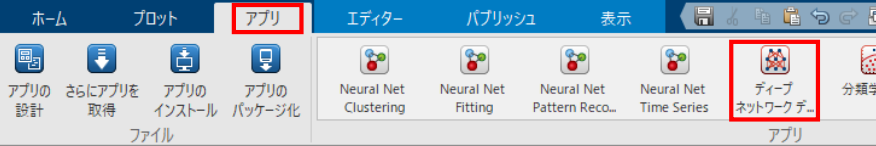

編集したいモデル(layersGeneratorかlayersDiscriminator)を選択し、OKボタンを押す。

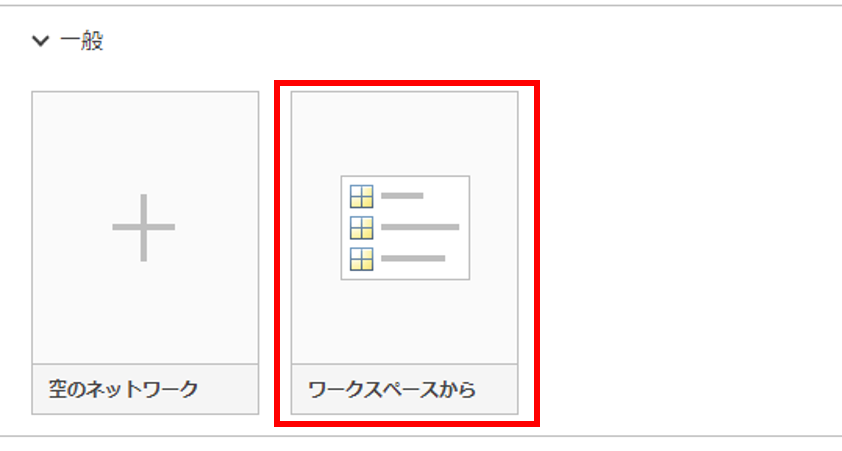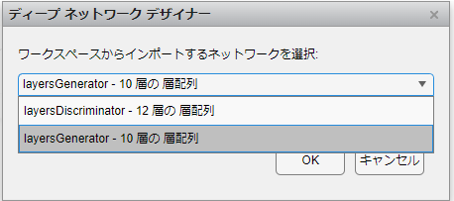

GeneratorやDiscriminatorの概要図は次のようになります。オレンジ色の部分は編集せずそれ以外の箇所を変更し性能を向上させましょう。

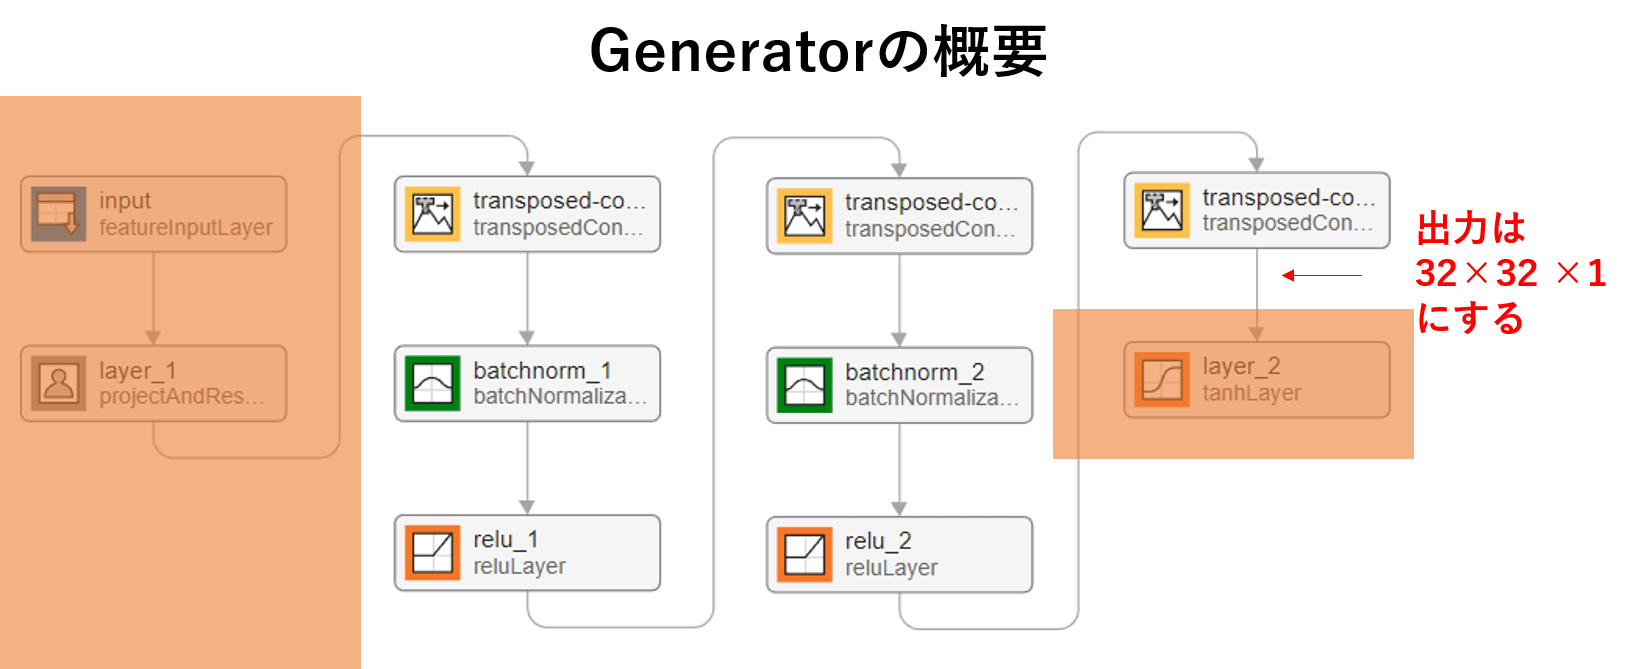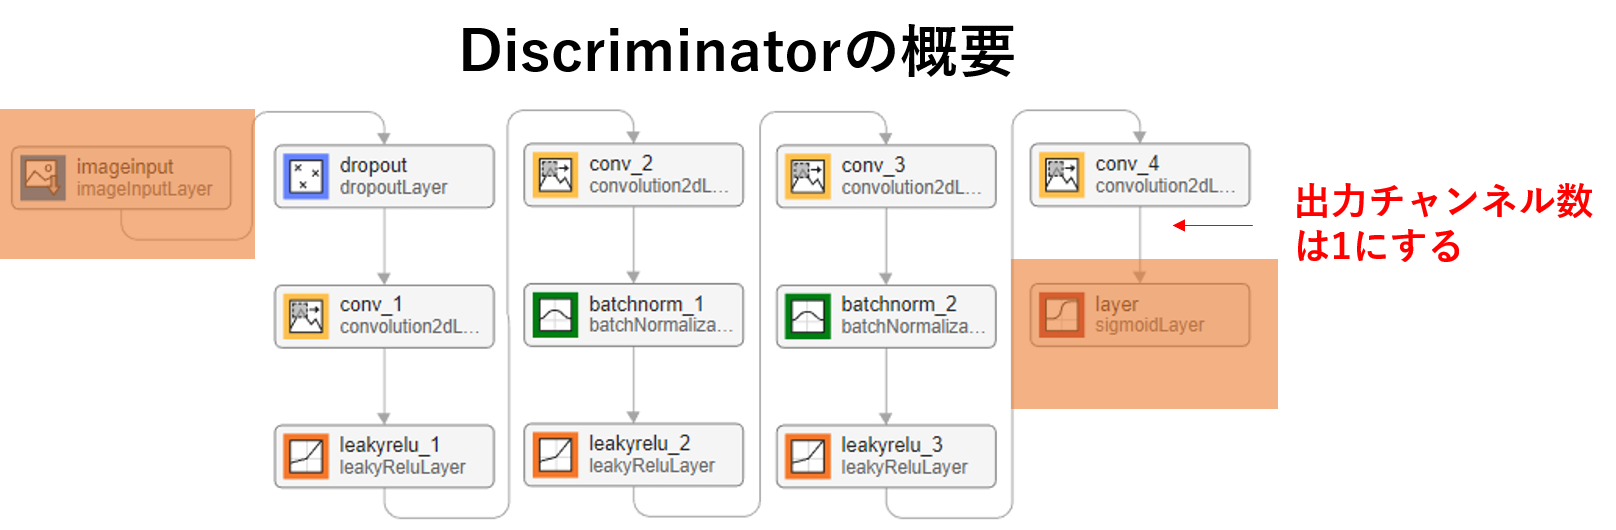

変更したら解析ボタンを押し、警告0、エラー2(デフォルトでエラーになります)ならばエクスポートボタンを押してください。

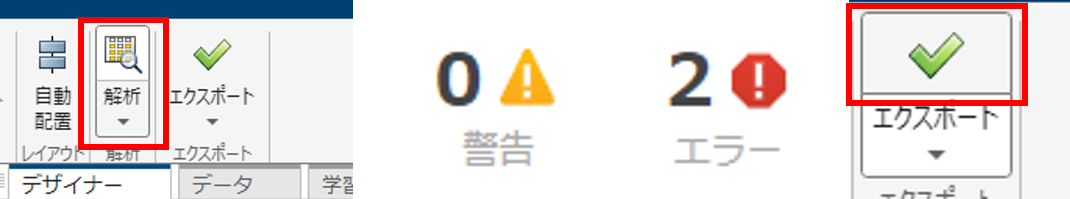

エクスポートが完了したら以下の画面が出てきます。layers_1などの名前は覚えておきましょう。

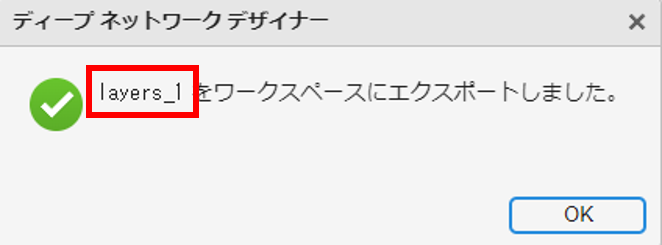

### Generatorの更新

エクスポートで出力されたモデル名を括弧の中にいれてください。(layers_1,layers_2など)

netG = dlnetwork(layers_1);

### Discriminatorの更新

エクスポートで出力されたモデル名を括弧の中にいれてください。(layers_1,layers_2など)

netD = dlnetwork(layers_5);

## 学習設定の定義

エポック数(学習回数)は5にしていますが、変更しても構いません。バッチサイズは変更して精度を比較してみてください。

ただしこれらのパラメータによって学習時間が大幅に伸びる可能性があるため注意してください。

numEpochs = 5;
miniBatchSize = 64;

学習率や勾配減衰率を設定することができます。

学習率は小さければ小さいほど細かな学習ができますが、学習が進みにくくなります。適切に設定しましょう。

勾配減衰率(gradientDecayFactor)と二乗移動平均(squaredGradientDecayFactor)は調節が難しいため初期値で固定しましょう。

learnRate = 0.0005;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

一般的にDiscriminatorはGeneratorよりも早く学習してしまいます。

するとDiscriminatorの損失が小さくなり勾配消失が発生しGeneratorの学習がうまく行かなくなります。

そこで本物の画像を偽物のラベルにすり替えることで識別器の学習を難しくし、学習バランスをとる手法があります。

flipProbは偽物のラベルにすり替える確率をしめしています。

反転確率flipProbは自由に設定してください。

flipProb = 0.35;

何回学習した時に画像を更新するかの値です。値が小さいほど細かく更新します。

validationFrequency = 20;

lambdaはモード崩壊用の損失関数の重みです。

lambdaの値を大きくすることでモード崩壊を軽減することができます。

0~2.0の範囲で調節するとうまく行くことが多いです。

lambda = 1.0;

## モデルの学習

**ここは変更しないでください。**

このセクションではモデルの学習を行います。

このセクションは実行するだけで生成された画像とグラフが表示されます。

青色のグラフがGeneratorのスコアで、オレンジ色がDiscriminatorのスコアです。

生成器のスコアは識別器を騙した割合を示しており、高いほどよい生成器であることを示しています。

識別器のスコアは与えられた画像が本物か偽物かを正しく判断した割合を示しており、高いほどよい識別機であることを示しています。

(生成器のスコアが100%になると識別器のスコアが0になるわけではありません。(実際の画像を正しく識別した場合があるため))

学習前設定のコード

augimds.MiniBatchSize = miniBatchSize;

mbq = minibatchqueue(augimds, ...
    MiniBatchSize=miniBatchSize, ...
    PartialMiniBatch="discard", ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");

trailingAvgG = [];
trailingAvgSqG = [];
trailingAvg = [];
trailingAvgSqD = [];

numValidationImages = 25;
ZValidation = randn(Noise_dim,numValidationImages,"single");
ZValidation = dlarray(ZValidation,"CB");

f = figure;
f.Position(3) = 2*f.Position(3);

imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);

C = colororder;
lineScoreG = animatedline(scoreAxes,Color=C(1,:));
lineScoreD = animatedline(scoreAxes,Color=C(2,:));
legend("Generator","Discriminator");
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

学習には時間が掛かります。(テスト稼動では6分ほど)

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs

    % Reset and shuffle datastore.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;

        % Read mini-batch of data.
        X = next(mbq);

        % Generate latent inputs for the generator network. Convert to
        % dlarray and specify the format "CB" (channel, batch). If a GPU is
        % available, then convert latent inputs to gpuArray.
        Z = randn(Noise_dim,miniBatchSize,"single");
        Z = dlarray(Z,"CB");

        % Evaluate the gradients of the loss with respect to the learnable
        % parameters, the generator state, and the network scores using
        % dlfeval and the modelLoss function.
        [~,~,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
            dlfeval(@modelLoss,netG,netD,X,Z,flipProb,lambda);
        netG.State = stateG;

        % Update the discriminator network parameters.
        [netD,trailingAvg,trailingAvgSqD] = adamupdate(netD, gradientsD, ...
            trailingAvg, trailingAvgSqD, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);

        % Update the generator network parameters.
        [netG,trailingAvgG,trailingAvgSqG] = adamupdate(netG, gradientsG, ...
            trailingAvgG, trailingAvgSqG, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);

        % Every validationFrequency iterations, display batch of generated
        % images using the held-out generator input.
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Generate images using the held-out generator input.
            XGeneratedValidation = predict(netG,ZValidation);

            % Tile and rescale the images in the range [0 1].
            I = imtile(extractdata(XGeneratedValidation));
            I = rescale(I)*255;

            % Display the images.
            subplot(1,2,1);
            image(imageAxes,I)
            colormap(gray)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end

        % Update the scores plot.
        subplot(1,2,2)
        scoreG = double(extractdata(scoreG));
        addpoints(lineScoreG,iteration,scoreG);

        scoreD = double(extractdata(scoreD));
        addpoints(lineScoreD,iteration,scoreD);

        % Update the title with training progress information.
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        drawnow
    end
end
% Generate images using the held-out generator input.
XGeneratedValidation = predict(netG,ZValidation);

% Tile and rescale the images in the range [0 1].
I = imtile(extractdata(XGeneratedValidation));
I = rescale(I)*255;

% Display the images.
subplot(1,2,1);
image(imageAxes,I)
colormap(gray)
xticklabels([]);
yticklabels([]);
title("Generated Images");
imwrite(frame2im(getframe(gcf)),"latest_result.png");

## 画像の生成

**ここは変更しないでください。**

このセクションではノイズをランダムで選び、画像を生成できます。

このセクションを実行するたびに結果が変わるため様々な結果を比較して、明瞭な結果を保存しましょう。

numObservations = 25;
ZNew = randn(Noise_dim,numObservations,"single");
ZNew = dlarray(ZNew,"CB");

Generatorで画像を生成。

XGeneratedNew = predict(netG,ZNew);

画像の表示。画像を保存するには画像右上の矢印マークを押し、保存してください。

I = imtile(extractdata(XGeneratedNew));
I = rescale(I)*255;
figure
image(I)
colormap(gray)
axis off
title("Generated Images")

## GANの損失関数定義

**ここは変更しないでください。**

このセッションではGANの損失関数とスコアについて解説します。

function [lossG,lossD,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
    modelLoss(netG,netD,X,Z,flipProb,lambda)

% Calculate the predictions for real data with the discriminator network.
layer_number = length(netD.Layers) - 2;
layer_name = netD.Layers(layer_number).Name;
[YReal,real_feature] = forward(netD,X,'Outputs',[netD.OutputNames,layer_name]);

% Calculate the predictions for generated data with the discriminator
% network.
[XGenerated,stateG] = forward(netG,Z);
[YGenerated,fake_feature] = forward(netD,XGenerated,'Outputs',[netD.OutputNames,layer_name]);

% Calculate the score of the discriminator.
scoreD = (mean(YReal) + mean(1-YGenerated)) / 2;

% Calculate the score of the generator.
scoreG = mean(YGenerated);

% Randomly flip the labels of the real images.
numObservations = size(YReal,4);
idx = rand(1,numObservations) < flipProb;
YReal(:,:,:,idx) = 1 - YReal(:,:,:,idx);

% Calculate the GAN loss.
[lossG, lossD] = ganLoss(real_feature,fake_feature,YReal,YGenerated,lambda);


% For each network, calculate the gradients with respect to the loss.
gradientsG = dlgradient(lossG,netG.Learnables,RetainData=true);
gradientsD = dlgradient(lossD,netD.Learnables);

end

## GANの損失関数とスコアについて

**ここは変更しないでください。**

GANは以下のような式で定義されています。

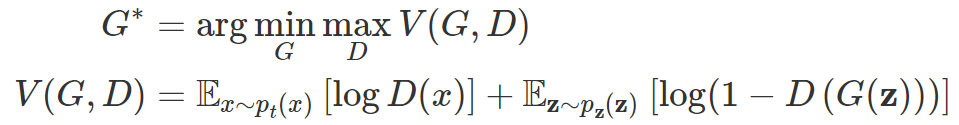

授業で習った通りこれらの式を展開していくと、GANはJensen-Shannonダイバージェンスを最適化するように学習することが分かります。

詳しくは[2]を参照してください。

今回はDiscriminatorの出力を$Y$ とすると

- $Y$ は入力画像が本物である確率を示しています。(1に近づけば本物と識別)

- $Y$が0に近づけば入力画像が偽物だと判断されます。

上記の損失関数を表現するとGeneratorの損失関数は次のようになります。

    
$$\textrm{lossGenerator}=-\textrm{mean}\left(\log \left(Y_{\textrm{Generated}} \right)\right),$$


ここで $Y_{Generated}$ はGeneratorで生成された画像を識別器で識別した出力です。

matlabでは右辺の値が小さくなるように学習するため、結果的に生成器は$Y_{Generated}$が1に近づく(本物に近づく)ように学習します。

Discriminatorの損失関数は次のようになります。

    
$$\textrm{lossDiscriminator}=-\textrm{mean}\left(\log \left(Y_{\textrm{Real}} \right)\right)-\textrm{mean}\left(\log \left(1-Y_{\textrm{Generated}} \right)\right),$$


ここで $Y_{Real}$ は本物の画像を識別器に入れた際の出力です。

この式から識別器は$Y_{Real}$は1に近づく(本物と見分ける)ように学習し、$Y_{\textrm{Generated}}$を0に近づく(偽物と見分ける)ように学習します。

しかし上記の損失関数では勾配消失が発生しやすいというデメリットがあります。

近年の研究ではCross Entropyを用いずにL1 Lossを用いると勾配消失が発生しにくいという研究があるため今回のコードではL1 Lossを使用しています。

 
$$\textrm{lossGenerator}=\textrm{mean}\left(Y_{\textrm{Generated}}^{2\;} \right),$$



$$\textrm{lossDiscriminator}=\textrm{mean}\left(Y_{\textrm{Real}}^2 \right)+\textrm{mean}\left({\left(1-Y_{\textrm{Generated}} \right)}^2 \right),$$


また、ラベル(本物なら1、偽物なら0)にノイズを入れることで安定し学習を促進させる手法があるためそれを用いている。詳しくは[3]を参照してください。

モード崩壊の対策手法はfeature matching[4]という手法を使用しています。

簡単に説明すると識別器で得られる本物の画像の特徴と偽物の特徴を近づけるように学習することによって生成器に特徴の多様性を学習させる手法になっています。

損失関数の考え方から生成器のスコアを設定すると、生成器は$Y_{\textrm{Generated}}$の値(騙した確率)が大きいほど性能のよい生成器であることが分かります。

    
$$\textrm{scoreGenerator}=\textrm{mean}\left(Y_{\textrm{Generated}} \right)\ldotp$$


一方識別器のスコアは本物と偽物を正確に識別できるほうがよい識別器と言えるため次のようなスコアを設定できます。

    
$$\textrm{scoreDiscriminator}=\frac{1}{2}\textrm{mean}\left(Y_{\textrm{Real}} \;\right)+\frac{1}{2}\textrm{mean}\left(1-Y_{\textrm{Generated}} \right)\ldotp$$


matlabで損失関数のコードは以下のようになります。

function [lossG,lossD] = ganLoss(real_feature,fake_feature,YReal,YGenerated,lambda)

real_mean_F = mean(real_feature,4);
fake_mean_F = mean(fake_feature,4);

lossG_image_loss = lambda * mean((real_mean_F - fake_mean_F).^2, "all");

% Calculate the loss for the discriminator network.
%lossD = -mean(log(YReal)) - mean(log(1-YGenerated));
Real_label = 1 - 0.2*rand(size(YReal));
Fake_label = 0.2*rand(size(YGenerated));
%lossD = mean((1 - YReal).^2) + mean(YGenerated.^2);
lossD = mean((Real_label - YReal).^2) + mean((Fake_label - YGenerated).^2);

% Calculate the loss for the generator network.
%lossG = -mean(log(YGenerated));
lossG = mean((1 - YGenerated).^2) + lossG_image_loss;

end

## ミニバッチ処理の関数定義

**ここは変更しないでください。**

ミニバッチ処理の関数を定義します。変更しないでください。

function X = preprocessMiniBatch(data)

% Concatenate mini-batch
X = cat(4,data{:});

% Rescale the images in the range [-1 1].
X = rescale(X,-1,1,InputMin=0,InputMax=255);

end

## References

- Radford, Alec, Luke Metz, and Soumith Chintala. “Unsupervised Representation Learning with Deep Convolutional Generative Adversarial Networks.” Preprint, submitted November 19, 2015. [http://arxiv.org/abs/1511.06434.](http://arxiv.org/abs/1511.06434.)

- [https://qiita.com/kzkadc/items/f49718dc8aedbe8a1bee](https://qiita.com/kzkadc/items/f49718dc8aedbe8a1bee)

- [https://qiita.com/underfitting/items/a0cbb035568dea33b2d7](https://qiita.com/underfitting/items/a0cbb035568dea33b2d7)

- Salimans, Tim, et al. "Improved techniques for training gans." *Advances in neural information processing systems* 29 (2016).